clear;close all; clc;

# EJERCICIO 4

## Modelo linealizado a 20 m/s en una carretera plana

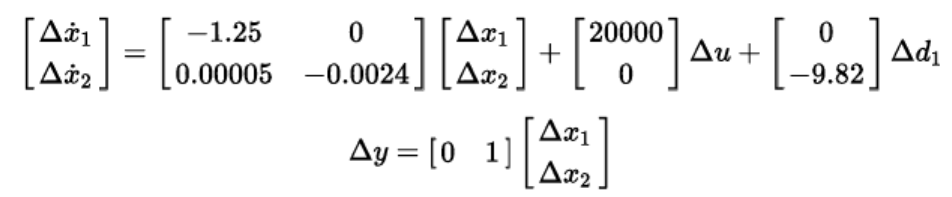

### 1. Verifique si el sistema es controlable.

run('CruiseCtrl_StateFeedback_design')
W  = [B A*B];

if (rank(W) == 2)
    disp('Es alcanzable y por lo tanto controlable')
else
    disp('No es completamente controlable')
end

Es alcanzable y por lo tanto controlable


### 2. Determine el polinomio deseado con ωn = 0.6 y ζ = $\frac{1}{\sqrt{2}}$

wn   = 0.6;
zeta = 1/sqrt(2);
p1   = -wn*zeta + i*wn*sqrt(1-zeta^2)

p1 = -0.4243 + 0.4243i

p2   = p1'

p2 = -0.4243 - 0.4243i

K    = acker(A, B, [p1 p2])

K =    -0.0000    0.3580


### 3. Determine el valor de kr. El vehículo está viajando a 20 m/s sobre una ruta plana. La perturbación se considera nula.

kr   = 1/(C*(-(A-B*K)\B))

kr = 0.3600

### 4. Utilice los archivos CruiseCtrl_StateFeedback.slx y CruiseCtrl_StateFeedback_design.m para graficar.

teta         = deg2rad(2); % Angulo de inclinación de la pendiente.
out          = sim("CruiseCtrl_StateFeedback_v2.slx")

out =   Simulink.SimulationOutput:

          ControlSignal: [1x1 struct] 
        VehicleVelocity: [1x1 struct] 
             WheelForce: [1x1 struct] 
                   tout: [40005x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


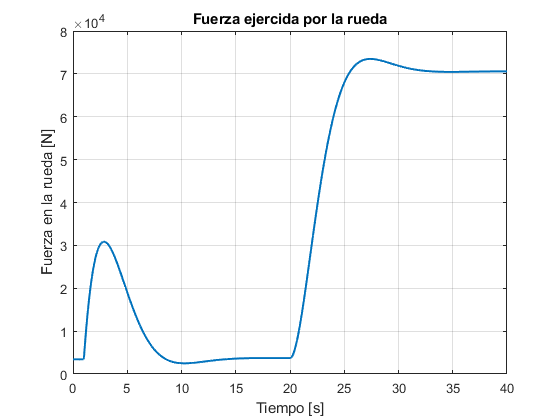

tWheelForce  = out.WheelForce.time;
WheelForce   = out.WheelForce.signals.values;

tVehicleVelocity    = out.VehicleVelocity.time;
VehicleVelocity     = out.VehicleVelocity.signals.values;

tControlSignal = out.ControlSignal.time;
ControlSignal  = out.ControlSignal.signals.values;

figure;
plot(tWheelForce, WheelForce, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Fuerza en la rueda [N]');
title('Fuerza ejercida por la rueda');
grid on;

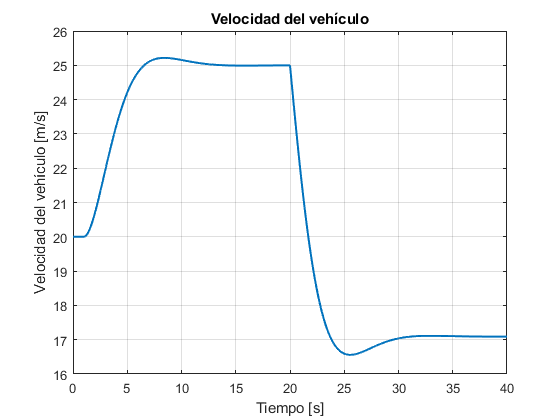

figure;
plot(tVehicleVelocity, VehicleVelocity, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Velocidad del vehículo [m/s]');
title('Velocidad del vehículo');
grid on;

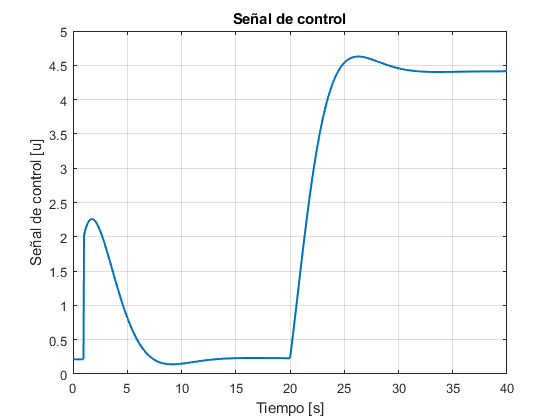

figure;
plot(tControlSignal, ControlSignal, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Señal de control [u]');
title('Señal de control');
grid on;

# EJERCICIO 5

#### 1. La velocidad del vehículo permanece constante mientras aumenta la fuerza de la rueda. F

#### 2. Primero, la velocidad del vehículo desciende un poco y la fuerza de la rueda aumenta. A continuación, la velocidad del vehículo recupera lentamente la velocidad de referencia actual. F

#### 3. La velocidad del vehículo desciende y luego asume una velocidad menor que la velocidad de referencia. V

#### 4. La velocidad del vehículo desciende y luego asume una velocidad mayor que la velocidad de referencia. F

# EJERCICIO 6

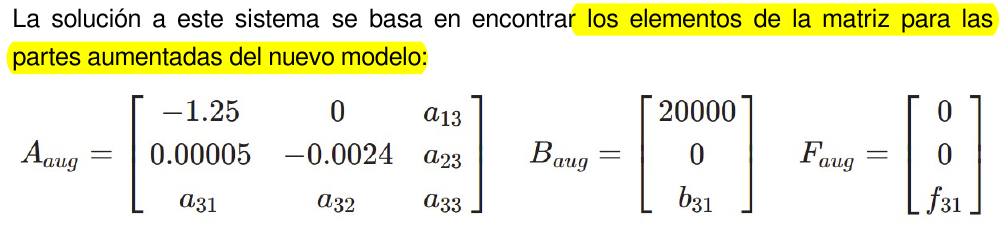

run('CruiseCtrl_StateFeedback_Int_design.m')
Aaug = [A  zeros(2, 1)
         C      0     ];
Baug = [B; 0];

#### 3. Hacer asignación de polos con los mismos p1 y p2 y con p3 dado por p3 = $-3\zeta\omega_{n}$

p3     = -3*zeta*wn;

Kaug  = acker(Aaug, Baug, [p1 p2 p3]);

# EJERCICIO 7

#### a) Analice la acción de control.

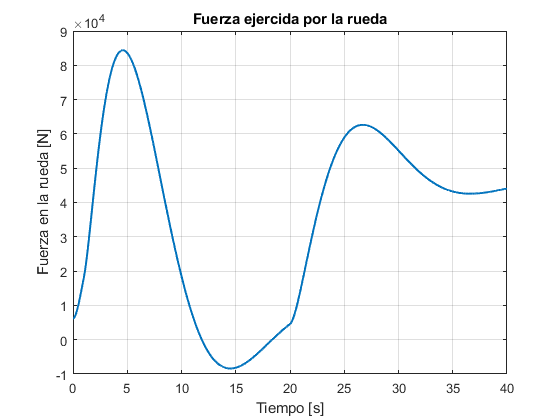

run('CruiseCtrl_StateFeedback_Int_design.m')
sim("CruiseCtrl_StateFeedback_Int.slx")
tWheelForceInt  = WheelForceInt.time;
WheelForceInt   = WheelForceInt.signals.values;

tVehicleVelocityInt    = VehicleVelocityInt.time;
VehicleVelocityInt     = VehicleVelocityInt.signals.values;

tControlSignalInt = ControlSignalInt.time;
ControlSignalInt  = ControlSignalInt.signals.values;

figure;
plot(tWheelForceInt, WheelForceInt, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Fuerza en la rueda [N]');
title('Fuerza ejercida por la rueda');
grid on;

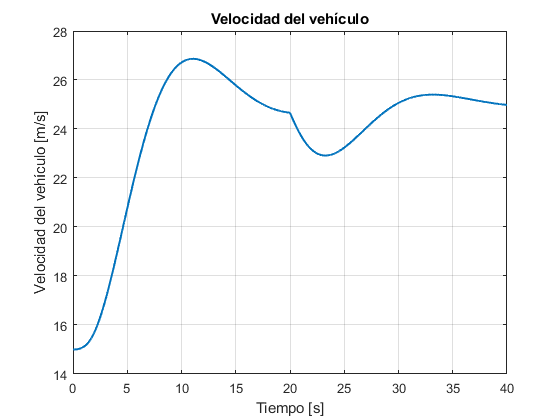

figure;
plot(tVehicleVelocityInt, VehicleVelocityInt, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Velocidad del vehículo [m/s]');
title('Velocidad del vehículo');
grid on;

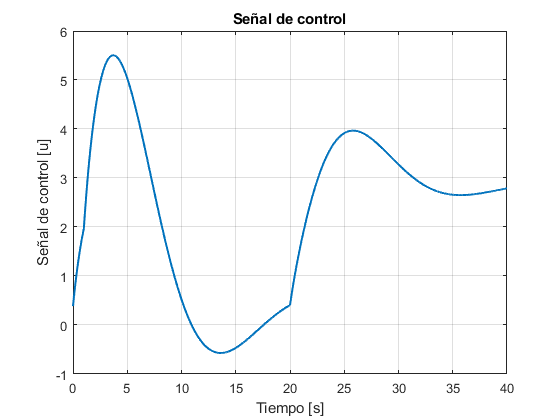

figure;
plot(tControlSignalInt, ControlSignalInt, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Señal de control [u]');
title('Señal de control');
grid on;

## **PREGUNTAS**

**1. La velocidad del vehículo permanece constante mientras aumenta la fuerza de la rueda. F**

**2. Primero, la velocidad del vehículo desciende un poco. Luego, la velocidad del vehículo recupera la velocidad de referencia actual. V**

**3. La velocidad del vehículo desciende y luego asume una velocidad menor que la velocidad de referencia. F**

**4. La velocidad del vehículo desciende y luego asume una velocidad mayor que la velocidad de referencia. F**

**5. La velocidad del vehículo y la fuerza de las ruedas comienzan a oscilar, cada una con una amplitud constante. F**

#### b) Cambiar la masa de 20000 a 40000

Hacer el cambio en el archivo de parámetros y luego:

run("CruiseCtrl_StateFeedback_Int_design.m");
sim("CruiseCtrl_StateFeedback_Int.slx")
tWheelForceInt  = WheelForceInt.time;
WheelForceInt   = WheelForceInt.signals.values;

tVehicleVelocityInt    = VehicleVelocityInt.time;
VehicleVelocityInt     = VehicleVelocityInt.signals.values;

tControlSignalInt = ControlSignalInt.time;
ControlSignalInt  = ControlSignalInt.signals.values;

figure;
plot(tWheelForceInt, WheelForceInt, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Fuerza en la rueda [N]');
title('Fuerza ejercida por la rueda');
grid on;


figure;
plot(tVehicleVelocityInt, VehicleVelocityInt, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Velocidad del vehículo [m/s]');
title('Velocidad del vehículo');
grid on;

figure;
plot(tControlSignalInt, ControlSignalInt, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Señal de control [u]');
title('Señal de control');
grid on;

## PREGUNTAS

**1. El sistema de control funciona. El rendimiento de la respuesta transitoria se ve afectado. El rebasamiento es mayor. V**

**2. El sistema de control funciona. El rendimiento de la respuesta transitoria se veafectado. Se elimina el pequeño sobreimpulso. F**

**3.El sistema de control funciona. El rendimiento de la respuesta transitoria no se veafectado. F**

**4.El sistema de control no funciona satisfactoriamente. No alcanza la velocidad de referencia después de que ha ocurrido la pendiente (perturbación). F**

**5.El sistema de control no funciona satisfactoriamente. El sistema comienza a oscilar cuando se produce la pendiente (perturbación). F**